# Actividad 4.1 (Evaluación)

Bruno Manuel Zamora Garcia A01798275

# **1. Trayectoria Ondas**

**Definición de la función de trayectoria:**

Para la trayectoria de ondas, definí que la componente x evoluciona de forma lineal, utilizando un vector generado de 0 a 5, y la componente y se calcula con la función:

  y = 2 · sin(x²)

De esta forma, cada valor de x tiene un valor de y asociado, lo que me permitió definir la trayectoria de referencia.

**Cálculo de velocidades y orientación:**

Una vez definida la trayectoria, utilicé la función *gradient* para obtener las derivadas de x e y con respecto al tiempo, lo que me dio dx/dt y dy/dt. Con estos datos, calculé la velocidad lineal (u) como la raíz cuadrada de la suma de los cuadrados de estas derivadas, es decir,

  u = √((dx/dt)² + (dy/dt)²).

Para determinar la orientación, usé la función *atan2(dy, dx)*, que me da el ángulo de la tangente de la trayectoria en cada instante. Finalmente, al derivar en el tiempo esta orientación, obtuve la velocidad angular.

**Integración de la cinemática:**

Implementé un ciclo for para integrar las ecuaciones de la cinemática del robot mediante el método de Euler. Con ello, pude actualizar la posición y la orientación del robot en función de las velocidades de referencia, simulando así el movimiento a lo largo de la trayectoria ondulada.

# **2. Trayectoria Círculo**

**Parametrización de la trayectoria:**

Para generar la trayectoria circular, utilicé la parametrización clásica de la circunferencia. Definí un ángulo θ que varía linealmente de 0 a 2π y, a partir de un radio fijo (r = 4), determiné las coordenadas usando:

  x = r · cos(θ)

  y = r · sin(θ)

Esto me permitió obtener una sucesión de puntos que conforman un círculo.

**Cálculo de la orientación y velocidades:**

Calculé la orientación de la trayectoria considerando las diferencias entre posiciones consecutivas; es decir, obtuve la diferencia en x y en y y apliqué *atan2* para cada segmento. De la distancia entre puntos consecutivos (dividida por el intervalo de tiempo) derivé la velocidad lineal, y a partir de la diferencia de orientación entre puntos obtuve la velocidad angular.

**Integración y simulación del movimiento:**

Nuevamente, implementé un ciclo for para integrar las velocidades y actualizar la posición y la orientación del robot usando el método de Euler. Esto me permitió simular cómo se desplaza el robot siguiendo la trayectoria circular, además de calcular las velocidades angulares de cada rueda mediante las ecuaciones de la cinemática diferencial.

# **3. Trayectoria Función a Trozos**

**Definición de la función a trozos:**

Para esta trayectoria, definí la función en función de la componente x, estableciendo diferentes expresiones para cada tramo:

  - Para x ≤ –1: y = 2 · x

  - Para –1 < x ≤ 1: y = 2 · x + 1

  - Para 1 < x < 4: y = –x + 4

  - Para x ≥ 4: y = x – 1

Generé un vector x que varió de –4 a 4 y, mediante un ciclo for, evalué la función correspondiente para cada valor de x.

**Obtención de velocidades y orientación:**

Al igual que en los casos anteriores, calculé las derivadas numéricas de x e y para obtener la velocidad lineal (u = √((dx/dt)² + (dy/dt)²)). La orientación en cada punto se determinó con *atan2(dy, dx)*, y derivando dicha orientación pude obtener la velocidad angular.

**Simulación e integración de la cinemática:**

Posteriormente, integré la cinemática del robot utilizando un ciclo for y el método de Euler, actualizando la posición y la orientación del robot a lo largo de la trayectoria definida por la función a trozos. Este proceso me permitió simular el movimiento del robot y analizar cómo las discontinuidades (propias de la función a trozos) impactan en la dinámica del sistema.

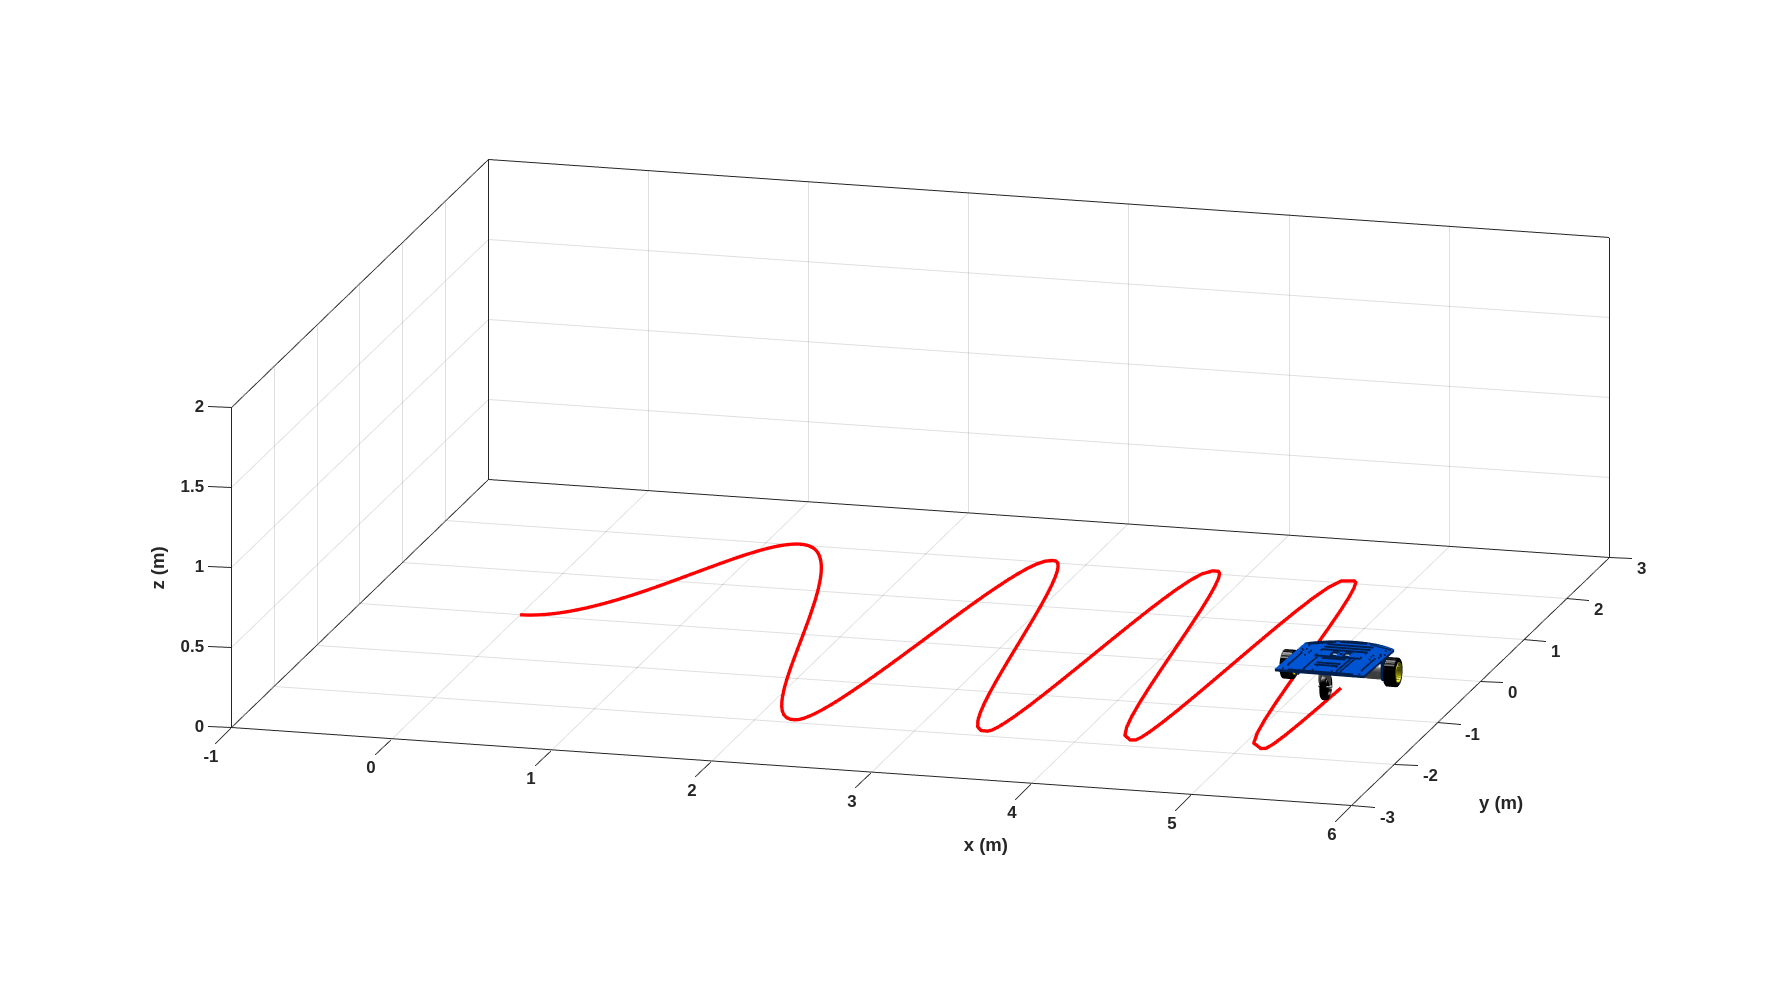

%% TRAYECTORIA 1: ONDAS
% trayectoria “ondulada” definida por:
%   x_ref: evoluciona linealmente de 0 a 5
%   y_ref: 2 * sin(x_ref.^2)

clear; close all; clc;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 20;             % Tiempo total de simulación (s)
ts = 0.1;            % Tiempo de muestreo (s)
t = 0:ts:tf;         % Vector de tiempo
N = length(t);

%%%%%%%%%%%%%%%%%%%%%%%% TRAYECTORIA 1: ONDAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x_ref = linspace(0, 5, N);
y_ref = 2 * sin(x_ref.^2);

% Cálculo de derivadas para velocidades de referencia
dx = gradient(x_ref, ts);
dy = gradient(y_ref, ts);
u = sqrt(dx.^2 + dy.^2);              % Velocidad lineal
theta_ref = atan2(dy, dx);            % Orientación deseada
w = gradient(theta_ref, ts);          % Velocidad angular

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1 = zeros(1, N+1);  % Posición en x
y1 = zeros(1, N+1);  % Posición en y
phi = zeros(1, N+1); % Orientación (theta)

x1(1) = x_ref(1);
y1(1) = y_ref(1);
phi(1) = theta_ref(1);

% Se usará el mismo punto de control que la posición
hx = zeros(1, N+1);
hy = zeros(1, N+1);
hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACIÓN %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for k = 1:N
    phi(k+1) = phi(k) + w(k)*ts;
    xp1 = u(k) * cos(phi(k+1));
    yp1 = u(k) * sin(phi(k+1));
    x1(k+1) = x1(k) + xp1 * ts;
    y1(k+1) = y1(k) + yp1 * ts;
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACIÓN VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%
scene1 = figure;
set(scene1, 'Color', 'white');
set(gca, 'FontWeight', 'bold');
sizeScreen = get(0, 'ScreenSize');
set(scene1, 'Position', sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
view([15 15]);
axis([-1 6 -3 3 0 2]);

scale = 4;
MobileRobot_5;  % Se requiere que esta función esté en el path
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), zeros(1,1), 'r', 'LineWidth', 2);

for k = 1:1:N
    delete(H1);
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end

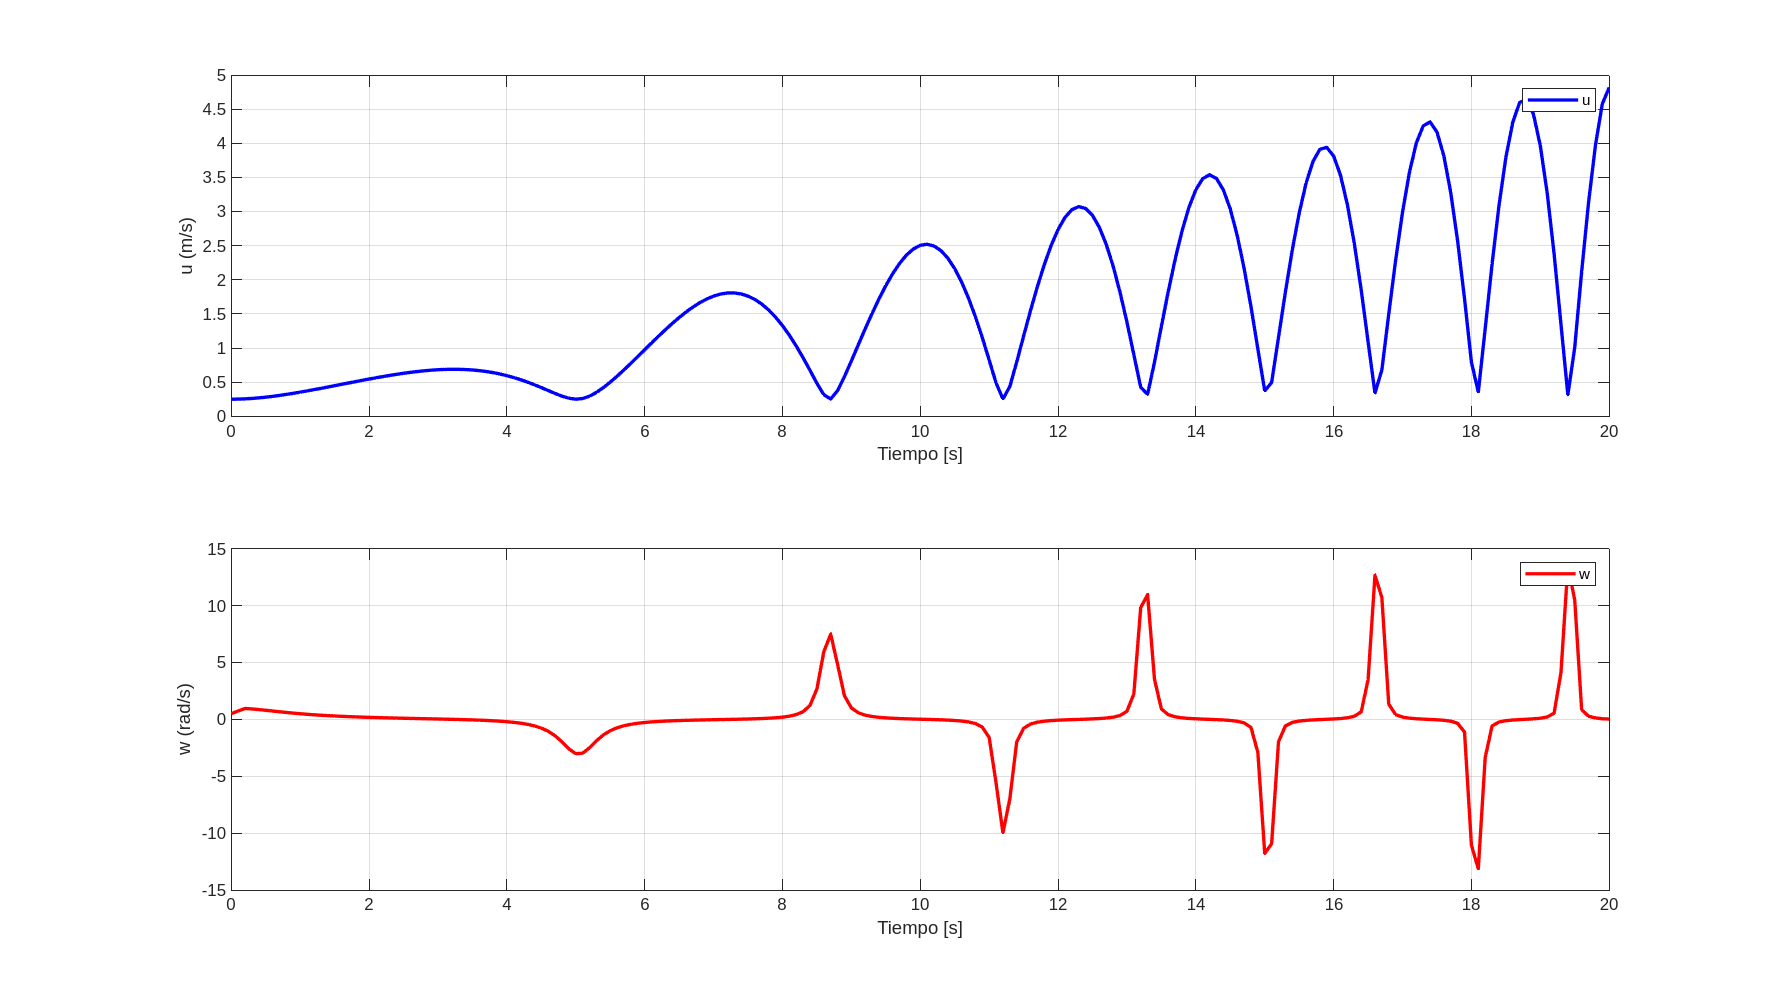


%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRÁFICAS AUXILIARES %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph1 = figure;
set(graph1, 'Position', sizeScreen);
subplot(211)
plot(t, u, 'b', 'LineWidth', 2); grid on; xlabel('Tiempo [s]'); ylabel('u (m/s)'); legend('u');
subplot(212)
plot(t, w, 'r', 'LineWidth', 2); grid on; xlabel('Tiempo [s]'); ylabel('w (rad/s)'); legend('w');

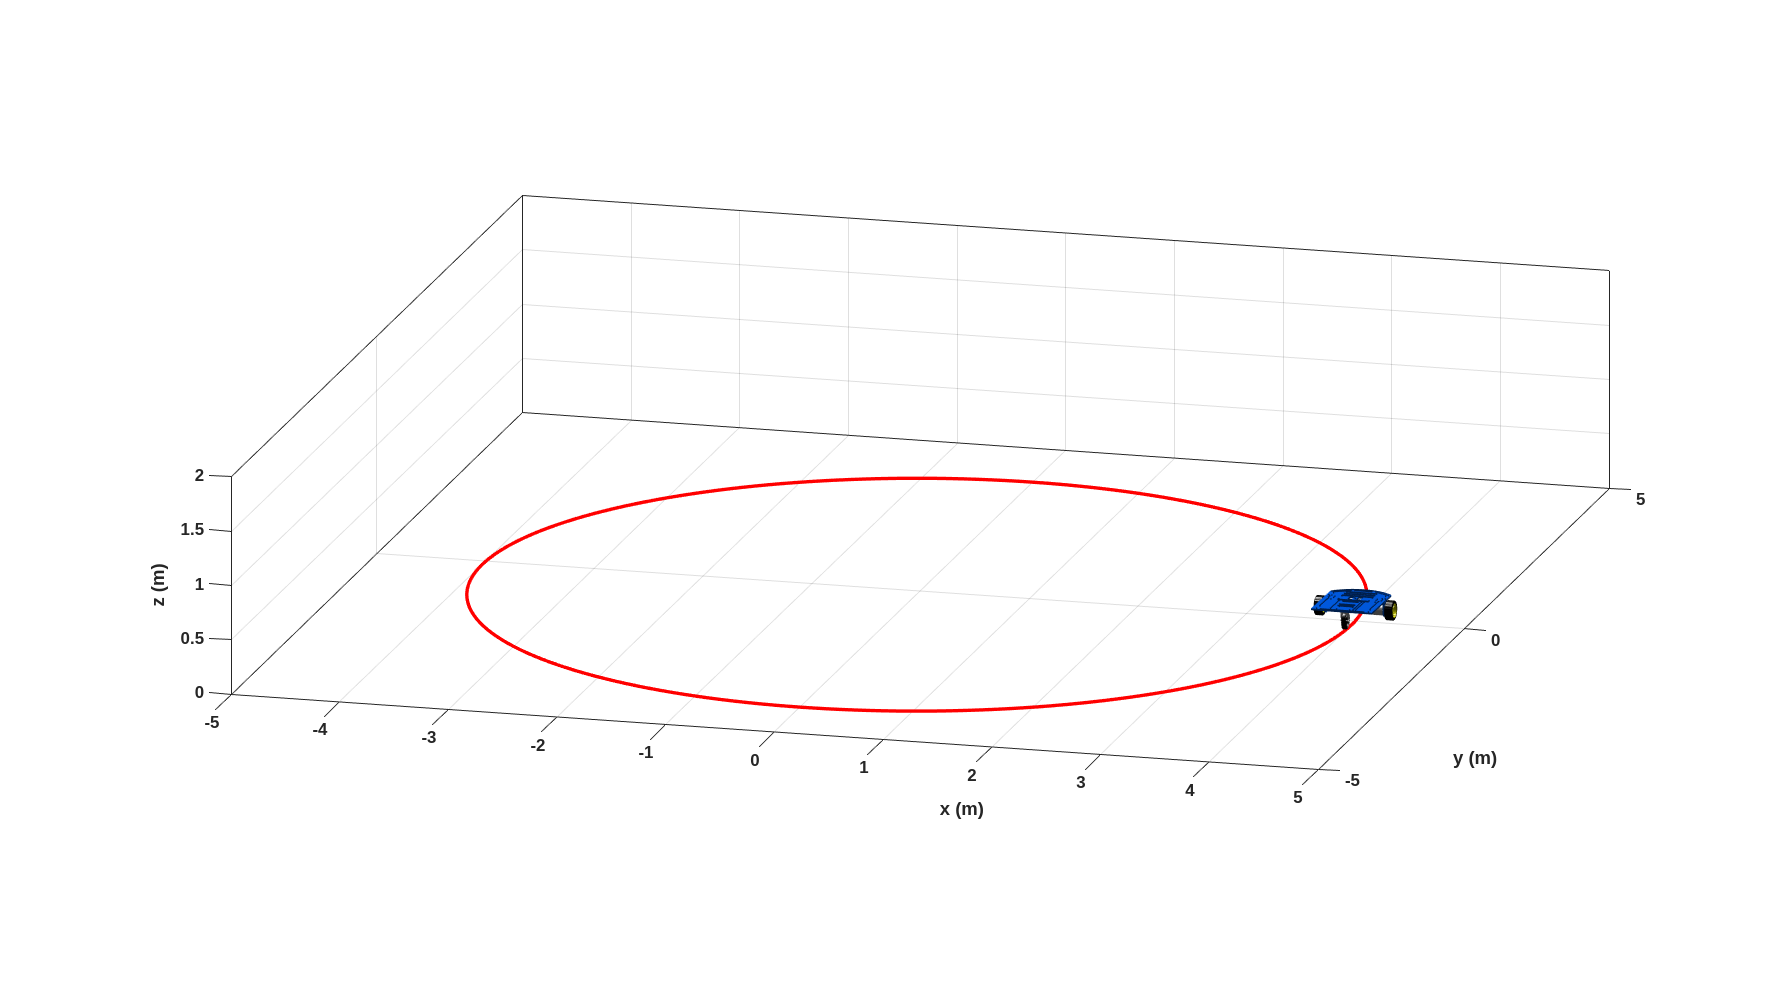


%% TRAYECTORIA 2: CÍRCULO
% trayectoria circular de radio 4, usando
% una parametrización en función del ángulo theta

% Se limpia la ventana de comandos pero se conservan las gráficas previas
clc;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 20;             % Tiempo total de simulación (s)
ts = 0.1;            % Tiempo de muestreo (s)
t = 0:ts:tf;         % Vector de tiempo
N = length(t) - 1;   % Número de intervalos para integración

%%%%%%%%%%%%%%%%%%%%%%%% TRAZADO DEL CÍRCULO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
theta_param = linspace(0, 2*pi, N+1);   % Ángulo de 0 a 2*pi
radius = 4;                             % Radio de la circunferencia
x_traj = radius * cos(theta_param);
y_traj = radius * sin(theta_param);

%%%%%%%%%%%%%%%%%%%% CALCULO DE LA ORIENTACIÓN DE REFERENCIA %%%%%%%%%%%%%%%%%%
phi_ref = zeros(1, N+1);
for k = 1:N
    dx_temp = x_traj(k+1) - x_traj(k);
    dy_temp = y_traj(k+1) - y_traj(k);
    phi_ref(k) = atan2(dy_temp, dx_temp);
end
phi_ref(end) = phi_ref(end-1);  % Ajuste para el último valor

%%%%%%%%%%%%%%%%%%% CÁLCULO DE VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%
u_circ = zeros(1, N);
w_circ = zeros(1, N);
for k = 1:N
    dx_temp = x_traj(k+1) - x_traj(k);
    dy_temp = y_traj(k+1) - y_traj(k);
    u_circ(k) = sqrt(dx_temp^2 + dy_temp^2) / ts;
    w_circ(k) = (phi_ref(k+1) - phi_ref(k)) / ts;
end

%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES DEL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%
x1 = zeros(1, N+1);
y1 = zeros(1, N+1);
phi = zeros(1, N+1);
x1(1) = x_traj(1);
y1(1) = y_traj(1);
phi(1) = phi_ref(1);

hx = x1;  % Trayectoria real (punto de control)
hy = y1;

%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACIÓN (INTEGRACIÓN) %%%%%%%%%%%%%%%%%%%%%%%
for k = 1:N
    phi(k+1) = phi(k) + w_circ(k)*ts;
    xp1 = u_circ(k)*cos(phi(k+1));
    yp1 = u_circ(k)*sin(phi(k+1));
    x1(k+1) = x1(k) + xp1*ts;
    y1(k+1) = y1(k) + yp1*ts;
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%% SIMULACIÓN VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%
scene2 = figure;
set(scene2, 'Color', 'white');
set(gca, 'FontWeight', 'bold');
set(scene2, 'Position', sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
view([15 15]);
axis([-5 5 -5 5 0 2]);

scale = 4;
MobileRobot_5;  % Función para dibujar el robot
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), zeros(1,1), 'r', 'LineWidth', 2);
for k = 1:1:N+1
    delete(H1);
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end

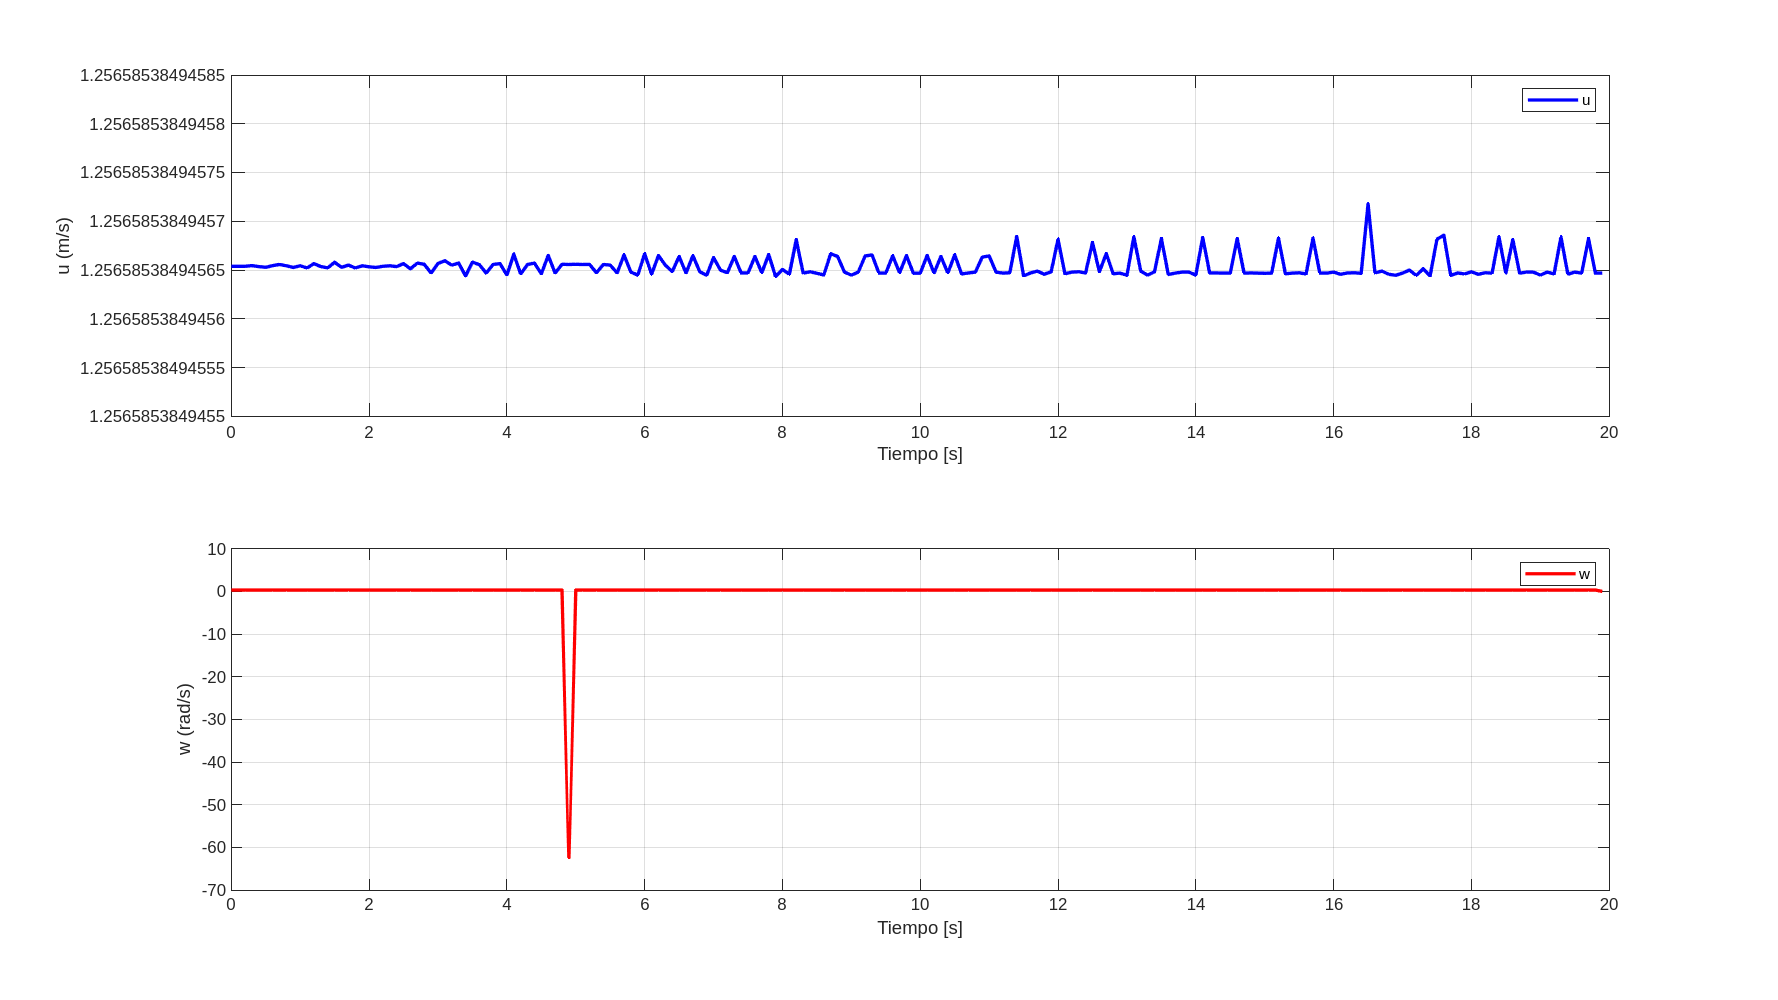


%%%%%%%%%%%%%%%%%%%%%%%% GRÁFICAS AUXILIARES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph2 = figure;
set(graph2, 'Position', sizeScreen);
subplot(211)
plot(t(1:N), u_circ, 'b', 'LineWidth', 2); grid on; xlabel('Tiempo [s]'); ylabel('u (m/s)'); legend('u');
subplot(212)
plot(t(1:N), w_circ, 'r', 'LineWidth', 2); grid on; xlabel('Tiempo [s]'); ylabel('w (rad/s)'); legend('w');

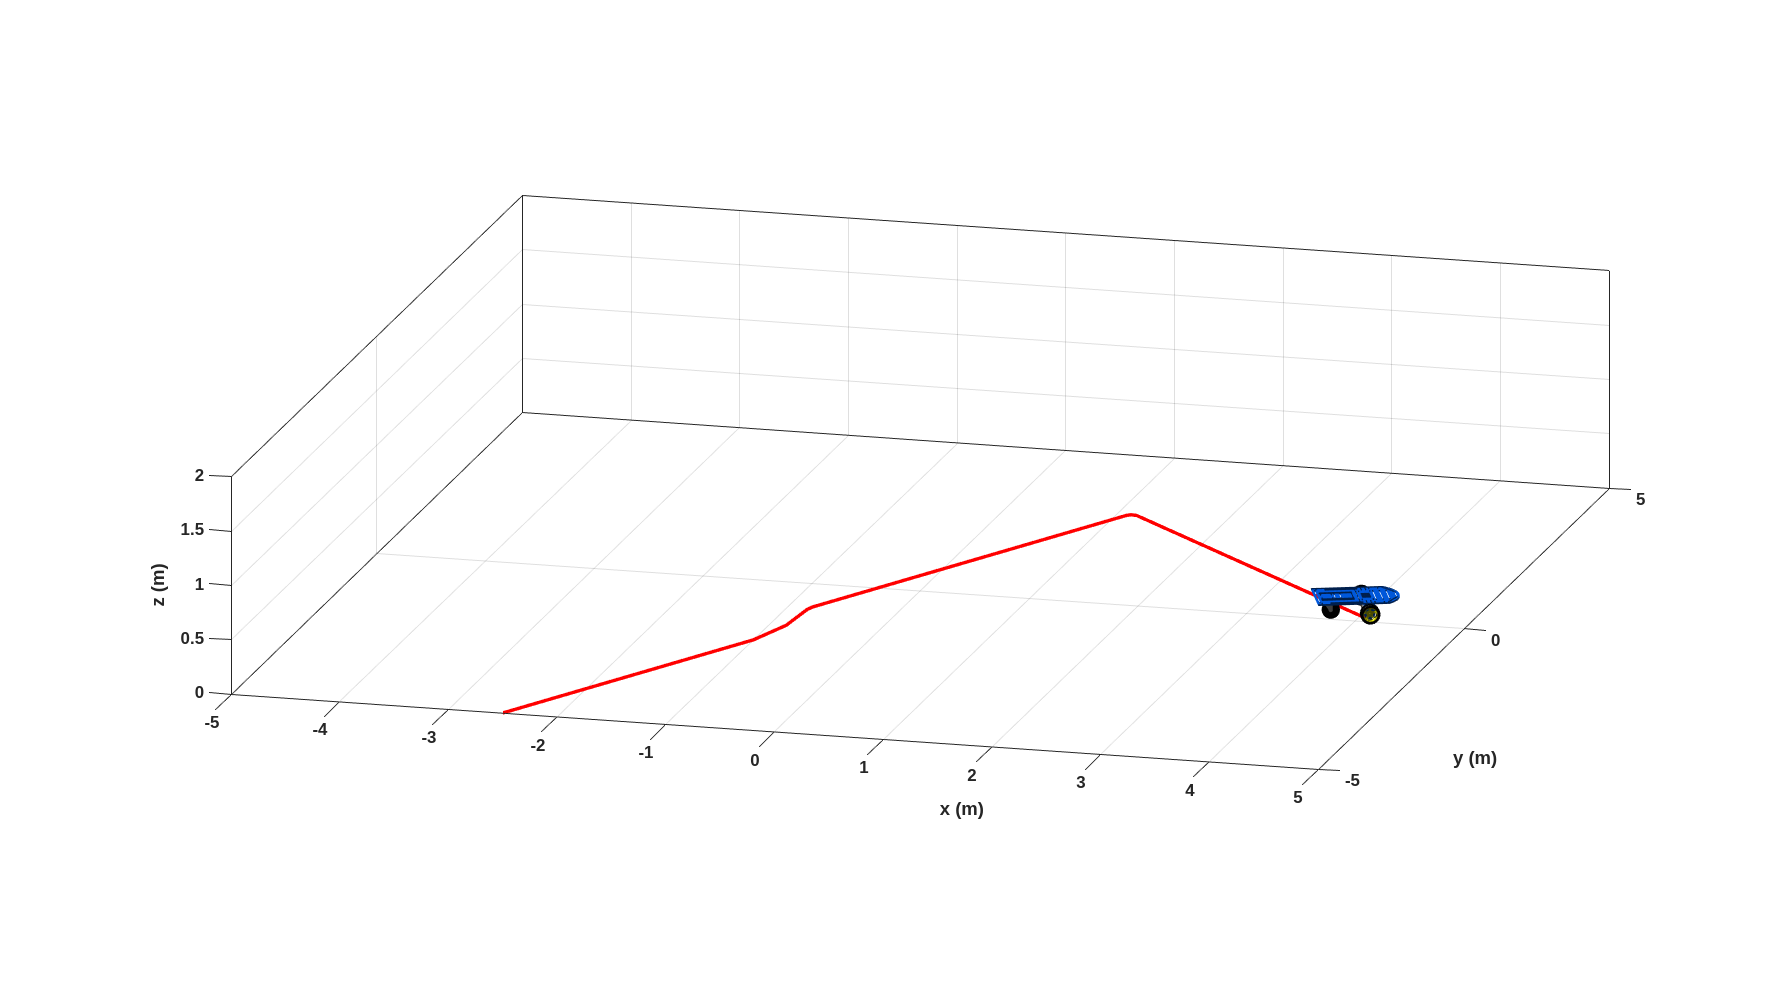

%% TRAYECTORIA 3: FUNCIÓN A TROZOS
% trayectoria definida por una función a trozos:
%   • Para x <= -1:      y = 2*x
%   • Para -1 < x <= 1:  y = 2*x + 1
%   • Para 1 < x < 4:    y = -x + 4
%   • Para x >= 4:       y = x - 1
% Se calcula la velocidad de referencia, la orientación y se integra la
% cinemática del robot para simular su movimiento.

% Nota: En este bloque se utiliza la misma estructura del ejemplo original
% para la función a trozos.

% No se usa clear/close all para que se puedan visualizar las gráficas anteriores
clc;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 20;             % Tiempo total de simulación (s)
ts = 0.1;            % Tiempo de muestreo (s)
t = 0:ts:tf;         % Vector de tiempo
N = length(t)-1;     % Número de muestras

%%%%%%%%%%%%%%%%%%% GENERACIÓN DE LA TRAYECTORIA %%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Se usa x como parámetro desde -4 hasta 4
x_path = linspace(-4, 4, N+1);
y_path = zeros(1, N+1);

% Función a trozos definida mediante if–elseif–else
for i = 1:length(x_path)
    if x_path(i) <= -1
        y_path(i) = 2 * x_path(i);
    elseif x_path(i) <= 1
        y_path(i) = 2 * x_path(i) + 1;
    elseif x_path(i) < 4
        y_path(i) = -x_path(i) + 4;
    else
        y_path(i) = x_path(i) - 1;
    end
end

% Cálculo de derivadas numéricas para obtener las velocidades de referencia
dx = gradient(x_path, ts);
dy = gradient(y_path, ts);
u_ref = sqrt(dx.^2 + dy.^2);   % Velocidad lineal
phi_ref = atan2(dy, dx);         % Orientación deseada
w_ref = gradient(phi_ref, ts);   % Velocidad angular

%%%%%%%%%%%%%%%%% CONDICIONES INICIALES DEL ROBOT %%%%%%%%%%%%%%%%%%%%%%%
x1 = zeros(1, N+1);  % Posición en x
y1 = zeros(1, N+1);  % Posición en y
phi = zeros(1, N+1); % Orientación (theta)
x1(1) = x_path(1);
y1(1) = y_path(1);
phi(1) = phi_ref(1);
hx = x1;  % El punto de control coincide con la posición inicial
hy = y1;

%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACIÓN (INTEGRACIÓN) %%%%%%%%%%%%%%%%%%%%%%
for k = 1:N
    phi(k+1) = phi(k) + w_ref(k)*ts;
    x1(k+1) = x1(k) + u_ref(k)*cos(phi(k))*ts;
    y1(k+1) = y1(k) + u_ref(k)*sin(phi(k))*ts;
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACIÓN VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%
scene3 = figure;
set(scene3, 'Color', 'white');
set(gca, 'FontWeight', 'bold');
set(scene3, 'Position', sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
view([15 15]);
axis([-5 5 -5 5 0 2]);

scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'LineWidth', 2);
for k = 1:1:N
    delete(H1);
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end

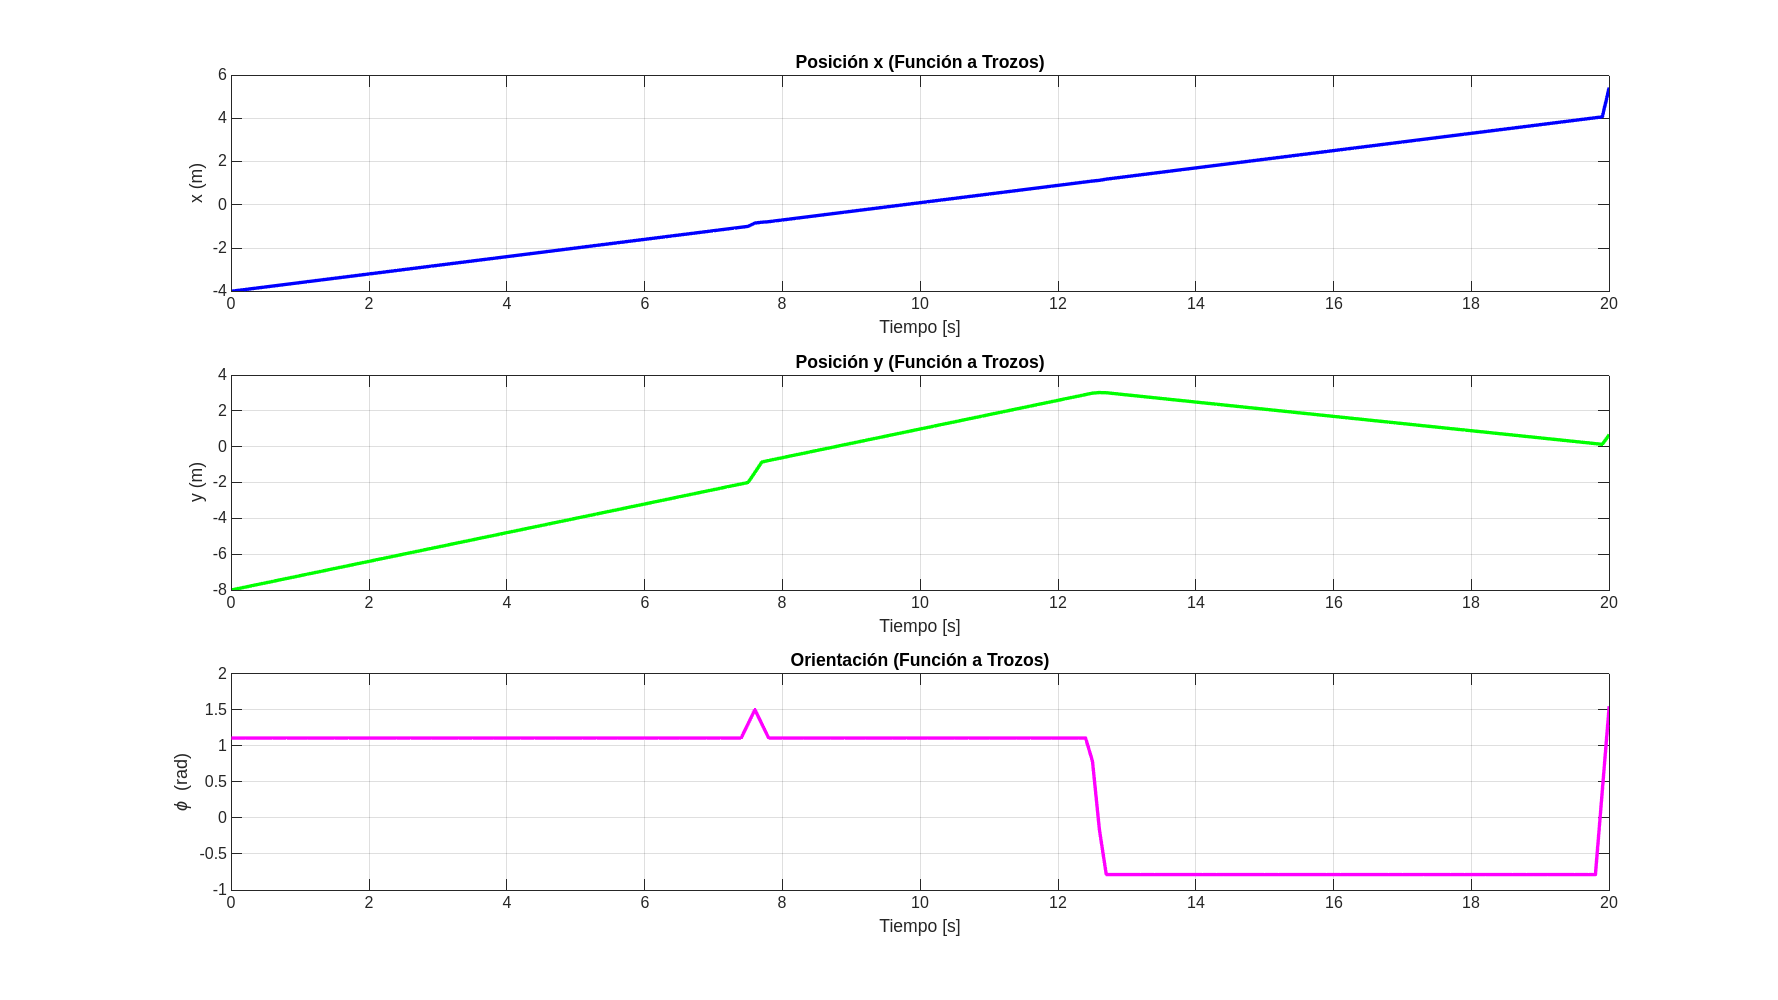


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRÁFICAS AUXILIARES %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph3 = figure;
set(graph3, 'Position', sizeScreen);
subplot(311)
plot(t, x1, 'b', 'LineWidth', 2); grid on; xlabel('Tiempo [s]'); ylabel('x (m)'); title('Posición x (Función a Trozos)');
subplot(312)
plot(t, y1, 'g', 'LineWidth', 2); grid on; xlabel('Tiempo [s]'); ylabel('y (m)'); title('Posición y (Función a Trozos)');
subplot(313)
plot(t, phi, 'm', 'LineWidth', 2); grid on; xlabel('Tiempo [s]'); ylabel('\phi (rad)'); title('Orientación (Función a Trozos)');

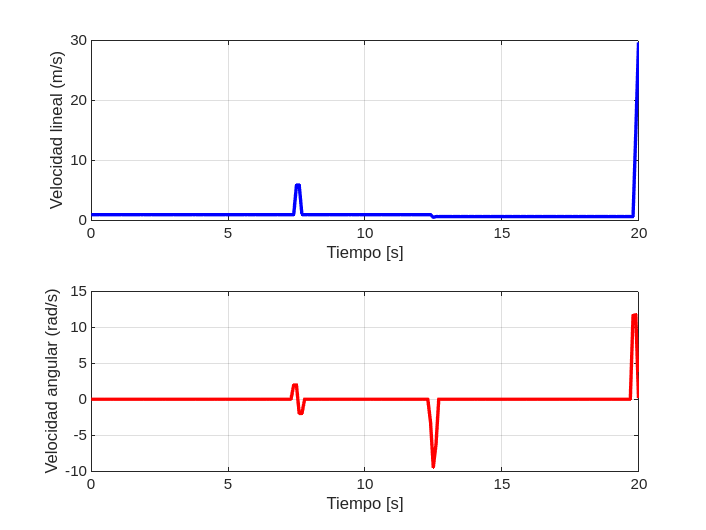


% Gráficas de velocidades de referencia para la función a trozos
vel_graph3 = figure;
subplot(211)
plot(t, u_ref, 'b', 'LineWidth', 2); grid on; xlabel('Tiempo [s]'); ylabel('Velocidad lineal (m/s)');
subplot(212)
plot(t, w_ref, 'r', 'LineWidth', 2); grid on; xlabel('Tiempo [s]'); ylabel('Velocidad angular (rad/s)');